## Set up the data classes

close
clear
clc
obj = UpperLimbModelOpenSimToolbox();

ans =
     []
ans =
     []



obj.model.Constraint_on = 0;

set the configuration

q_init = [0.3 ; 0.2; 0; 1; 1; 0.2; 1]

q_init =     0.3000
    0.2000
         0
    1.0000
    1.0000
    0.2000
    1.0000


## Nullspace motion Algorithm (1)

T_init = eye(4);
[~, T_init(1:3,4), T_init(1:3,1:3)] = obj.forwardKinematics(q_init);
J = obj.model.getJacobian_mp_sub(1, obj.coord_list);
delta_q_last = null(J);

steps = 4000

steps = 4000

T = cell(1,steps);
q = cell(1,steps);
q_null = q_init;
for iNull = 1:steps
    T_s = eye(4);
    [~, T_s(1:3,4), T_s(1:3,1:3)] = obj.forwardKinematics(q_null);
    T{iNull} = T_s;
    q{iNull} = q_null;

    J = obj.model.getJacobian_mp_sub(1, obj.coord_list);
    nullvec = null(J);
    direction = dot(nullvec,delta_q_last);
    if direction < 0
        nullvec = - nullvec;
    elseif direction < 0.2
        disp("Direction vector close to orthogonal! " + direction);
    end
    
    q_value_temp = q_null + 0.005 * nullvec;
    [configSol, solInfo] = inverseKinematics(obj, q_value_temp, T_init);
    if solInfo.iteration > 1
        delta_q_last = (configSol - q_null) / norm(configSol - q_null);
        q_value_temp = configSol;
    else
        delta_q_last = nullvec;
    end
    q_null = q_value_temp;
end

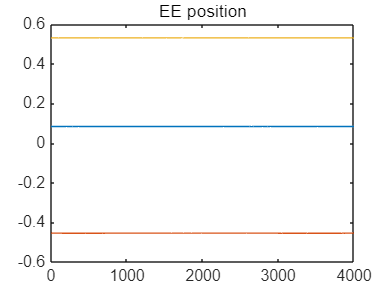

x = 1:steps;

figure()
T_mtx = cat(3,T{:});
plot(x,squeeze(T_mtx(1,4,:)),x,squeeze(T_mtx(2,4,:)),x,squeeze(T_mtx(3,4,:)))
title("EE position");

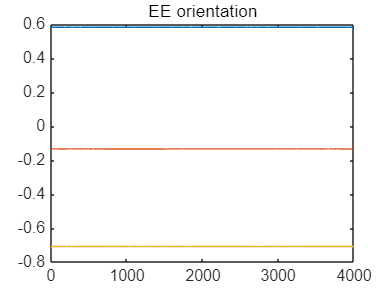


figure()
eul = rotm2eul(T_mtx(1:3,1:3,:));
plot(x,eul(:,1),x,eul(:,2),x,eul(:,3));
title("EE orientation");

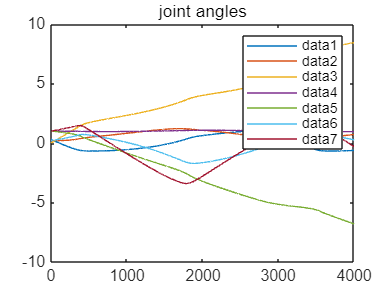


figure()
q_mtx = [q{:}];
plot(x,q_mtx(1,:),x,q_mtx(2,:),x,q_mtx(3,:),x,q_mtx(4,:),x,q_mtx(5,:),x,q_mtx(6,:),x,q_mtx(7,:))
title("joint angles");
legend()